# TV models

- Prepare time-varying models

- Identify a SVAR using Cholesky

- Checking TV features of the model (beta/sigma) in estimation/IRF/forecast



clear
close all
rehash path

addpath ../sandbox
addpath ../bear


## Convenience functions

percentiles = [10, 50, 90];

prctileFunc = @(x) prctile(x, percentiles, 2);

extremesFunc = @(x) [min(x, [], 2), max(x, [], 2)];


## Prepare data and a reduced-form model

inputTbx = tablex.fromCsv("SV.csv");

estimStart = datex.q(1971,2);
estimEnd = datex.q(2020,1);
estimSpan = datex.span(estimStart, estimEnd);

meta = model.Meta( ...
    endogenous=["YER", "HICSA", "STN"], ...
    units="", ...
    exogenous=[], ...
    order=4, ...
    intercept=true, ...
    estimationSpan=estimSpan, ...
    ...
    identificationHorizon=20, ...
    shockConcepts=["DEM", "SUP", "POL"] ...
);

dataH = model.DataHolder(meta, inputTbx);


## Time-varying models

Time-varying coefficients (BetaTV)


estimatorR1 = estimator.BetaTV(meta);

modelR1 = model.ReducedForm( ...
    meta=meta ...
    , dataHolder=dataH ...
    , estimator=estimatorR1 ...
    , stabilityThreshold=Inf ...
);

modelR1.Estimator.Settings

ans =   BetaTV with properties:

            Burnin: 0
         Exogenous: [3×1 logical]
    BlockExogenous: 0
    Autoregression: [3×1 double]
           Lambda1: 0.1000
           Lambda2: 0.5000
           Lambda3: 1
           Lambda4: [3×1 double]
           Lambda5: 1.0000e-03


and General time-varying (i.e parameters and covariance are both TV)


estimatorR2 = estimator.GeneralTV(meta);

modelR2 = model.ReducedForm( ...
    meta=meta ...
    , dataHolder=dataH ...
    , estimator=estimatorR2 ...
    , stabilityThreshold=Inf ...
);
modelR2.Estimator.Settings

ans =   GeneralTV with properties:

                              Burnin: 0
                           Exogenous: [3×1 logical]
                      BlockExogenous: 0
                      Autoregression: [3×1 double]
                             Lambda1: 0.1000
                             Lambda2: 0.5000
                             Lambda3: 1
                             Lambda4: [3×1 double]
                             Lambda5: 1.0000e-03
    HeteroskedasticityAutoRegression: 1
             HeteroskedasticityShape: 1.0000e-03
             HeteroskedasticityScale: 1.0000e-03


## Indentify a SVAR using Cholesky (without reordering)

Time-varying coefficients (BetaTV)


identChol = identifier.Cholesky(order=[]);

modelS1 = model.Structural(reducedForm=modelR1, identifier=identChol);
modelS1.initialize();
info1 = modelS1.presample(1000);


 Presampling model.Structural (BetaTV) [1000]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



modelS1.Presampled{1}

ans = struct with fields:
                  beta: {196×1 cell}
                 omega: [39×1 double]
                 sigma: [3×3 double]
    IdentificationDraw: [1×1 struct]
                     D: [3×3 double]


modelS1.Presampled{1}.IdentificationDraw

ans = struct with fields:
        A: {20×1 cell}
        C: {20×1 cell}
    Sigma: [3×3 double]


modelS1.Presampled{1}.IdentificationDraw.A{1,1}

ans =    -0.6153    0.3490   -0.2003
   -0.2767   -0.0332    0.2812
    0.6245    0.1102   -4.6361
    0.5351    0.0388   -1.8665
   -0.5875   -0.2427   -2.5270
   -1.1210   -0.5502    2.1181
   -0.0618    0.0823    0.1006
   -0.7082   -0.3488   -0.1461
   -0.5697    0.1393   -1.3498
   -0.0547    0.0346    0.6792


modelS1.Presampled{1}.IdentificationDraw.A{2,1}

ans =    -0.6762    0.3513   -0.1863
   -0.2278   -0.0921    0.5574
    0.6243    0.1105   -5.0362
    0.5120    0.0383   -1.8599
   -0.5873   -0.2426   -2.5201
   -1.1204   -0.5502    2.0677
   -0.0683    0.0824    0.0984
   -0.7876   -0.3521   -0.1410
   -0.5689    0.1395   -1.3499
   -0.0551    0.0345    0.6793


and General time-varying


modelS2 = model.Structural(reducedForm=modelR2, identifier=identChol);
modelS2.initialize();
info2 = modelS2.presample(1000);


 Presampling model.Structural (GeneralTV) [1000]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



modelS2.Presampled{1}

ans = struct with fields:
                  beta: {196×1 cell}
                 omega: [39×1 double]
                     F: [3×3 double]
                  sbar: [3×1 double]
                     L: {196×1 cell}
                   phi: [5.5347e-06 5.3758e-06 5.0265e-06]
              sigmaAvg: [9×1 double]
              lambda_t: {196×1 cell}
               sigma_t: {196×1 cell}
    IdentificationDraw: [1×1 struct]
                     D: [3×3 double]


modelS2.Presampled{1}.IdentificationDraw

ans = struct with fields:
        A: {20×1 cell}
        C: {20×1 cell}
    Sigma: [3×3 double]


modelS2.Presampled{1}.IdentificationDraw.A{1,1}

ans =     0.2841   -0.1258   -0.1150
    1.0269   -1.2504   -0.0992
   -0.8944   -0.3906    3.4805
    1.8769    0.2772    0.1469
   -0.0391    0.0255    1.5594
   -0.3354   -0.0368   -2.6967
    0.0117    0.0464   -0.3957
   -0.0017    0.6513    0.7248
    0.0241    0.1063   -0.1423
   -0.0344   -0.1555    0.0491


modelS2.Presampled{1}.IdentificationDraw.A{2,1}

ans =     0.3664   -0.1285   -0.1081
    1.1039   -0.7772   -0.6959
   -0.8938   -0.3897    3.6781
    1.8650    0.2771    0.1355
   -0.0391    0.0255    1.3182
   -0.3372   -0.0364   -2.9412
   -0.0061    0.0461   -0.3909
    0.1360    0.7240    0.7189
    0.0231    0.1063   -0.1515
   -0.0305   -0.1554    0.0497


## Impulse responses

Time-varying coefficients (BetaTV)

respTbx1 = modelS1.simulateResponses();
respTbx1 = tablex.apply(respTbx1, prctileFunc);
respTbx1 = tablex.flatten(respTbx1);

respTbx1

respTbx1 = 24×9 timetable
     Time                    YER___DEM                                YER___SUP                                 YER___POL                               HICSA___DEM                                HICSA___SUP                               HICSA___POL                              STN___DEM                               STN___SUP                               STN___POL             
    _______    _____________________________________    ______________________________________    _____________________________________    ______________________________________    _______________________________________    _____________________________________    _______________________________

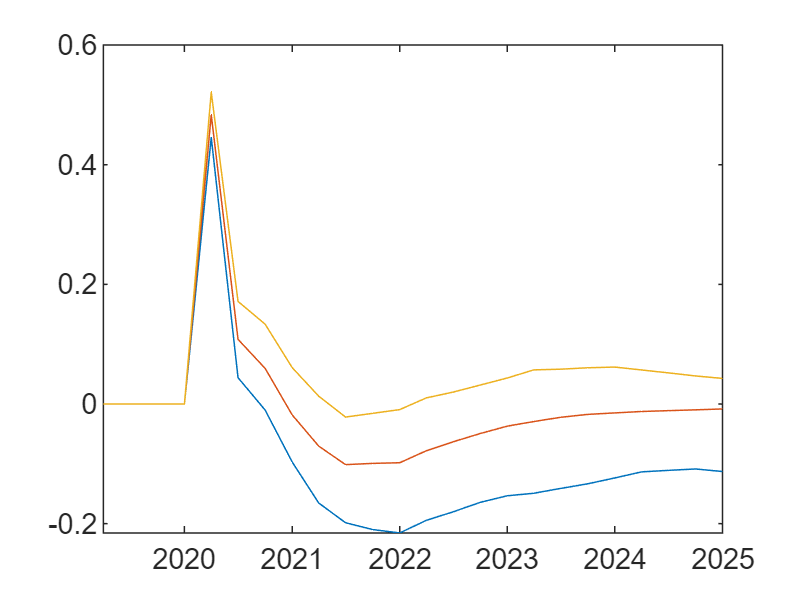

ans =   3×1 Line array:

  Line
  Line
  Line



tablex.plot(respTbx1,"YER___DEM")

and General time-varying

respTbx2 = modelS2.simulateResponses();
respTbx2 = tablex.apply(respTbx2, prctileFunc);
respTbx2 = tablex.flatten(respTbx2);

respTbx2

respTbx2 = 24×9 timetable
     Time                    YER___DEM                                YER___SUP                              YER___POL                               HICSA___DEM                                HICSA___SUP                                HICSA___POL                               STN___DEM                                 STN___SUP                                  STN___POL               
    _______    _____________________________________    _____________________________________    __________________________________    _______________________________________    _______________________________________    _______________________________________    __________________________

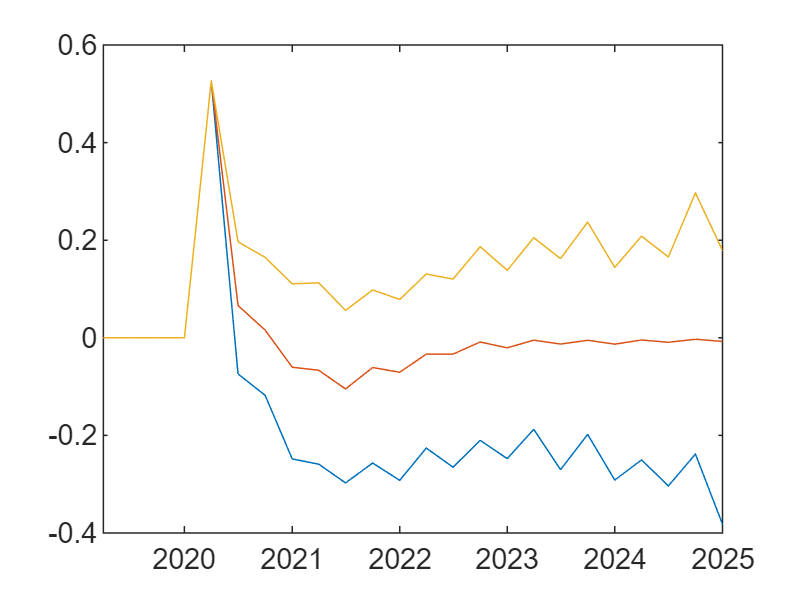

ans =   3×1 Line array:

  Line
  Line
  Line



tablex.plot(respTbx2,"YER___DEM")

## Unconditional forecast 


fcastStart = datex.shift(modelS1.Meta.EstimationEnd, -10);
fcastEnd = datex.shift(modelS1.Meta.EstimationEnd, 0);
fcastSpan = datex.span(fcastStart, fcastEnd);


Time-varying coefficients (BetaTV)

fcastTbx1 = modelS1.forecast(fcastSpan);
fcastPrctileTbx1 = tablex.apply(fcastTbx1, prctileFunc);
fcastPrctileTbx1 = tablex.flatten(fcastPrctileTbx1);

fcastTbx1

fcastTbx1 = 15×6 timetable
     Time           YER             HICSA             STN           resid_YER       resid_HICSA       resid_STN  
    _______    _____________    _____________    _____________    _____________    _____________    _____________

    2016-Q3    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double
    2016-Q4    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double
    2017-Q1    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double
    2017-Q2    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double

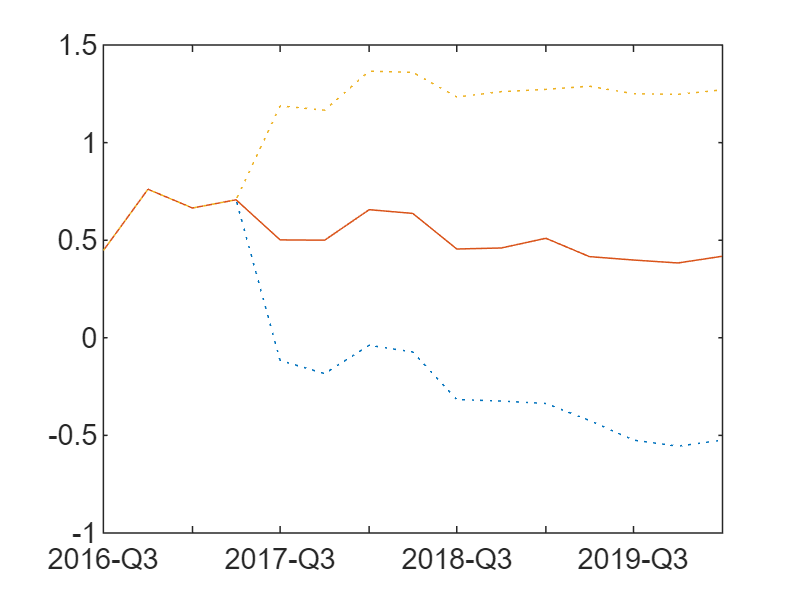


tablex.plot( ...
    fcastPrctileTbx1, "YER", ...
    plotSettings={{"lineStyle"}, {":"; "-"; ":"}} ...
);

and General time-varying

fcastTbx2 = modelS2.forecast(fcastSpan);
fcastPrctileTbx2 = tablex.apply(fcastTbx2, prctileFunc);
fcastPrctileTbx2 = tablex.flatten(fcastPrctileTbx2);

fcastTbx2

fcastTbx2 = 15×6 timetable
     Time           YER             HICSA             STN           resid_YER       resid_HICSA       resid_STN  
    _______    _____________    _____________    _____________    _____________    _____________    _____________

    2016-Q3    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double
    2016-Q4    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double
    2017-Q1    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double
    2017-Q2    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double

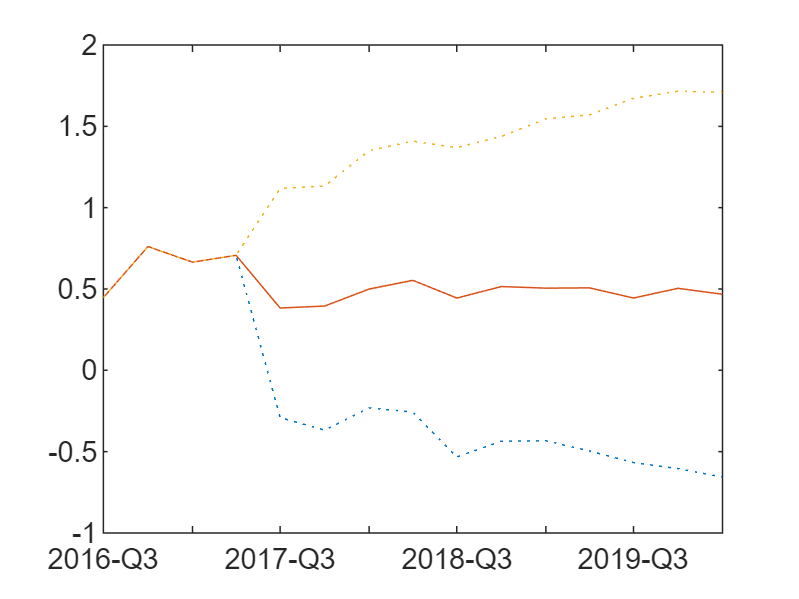


tablex.plot( ...
    fcastPrctileTbx2, "YER", ...
    plotSettings={{"lineStyle"}, {":"; "-"; ":"}} ...
);